clc;
clear all;
% initialization
% rng(41)

% r = 21.4597
% syms N 'real'
% eqn = r == 100*sqrt(log(N)/N)
% fx = solve(eqn)
% double(fx)


N = 100 % number of nodes

N = 100

% randomly distributed nodes
r = 100*sqrt(2*log(N)/N) % coverage of nodes

r = 30.3485

nodes_xaxis = 100*rand(N,1);
nodes_yaxis = 100*rand(N,1);

% grid of nodes
% r = 10
% nodes_xaxis = [5:10:100,5:10:100,5:10:100,5:10:100,5:10:100,5:10:100,5:10:100,5:10:100,5:10:100,5:10:100]'
% nodes_yaxis = [5*ones(1,10),15*ones(1,10),25*ones(1,10),35*ones(1,10),45*ones(1,10),55*ones(1,10),65*ones(1,10),75*ones(1,10),85*ones(1,10),95*ones(1,10)]'

nodes = [nodes_xaxis,nodes_yaxis]; 
max_iter = 50000

max_iter = 50000

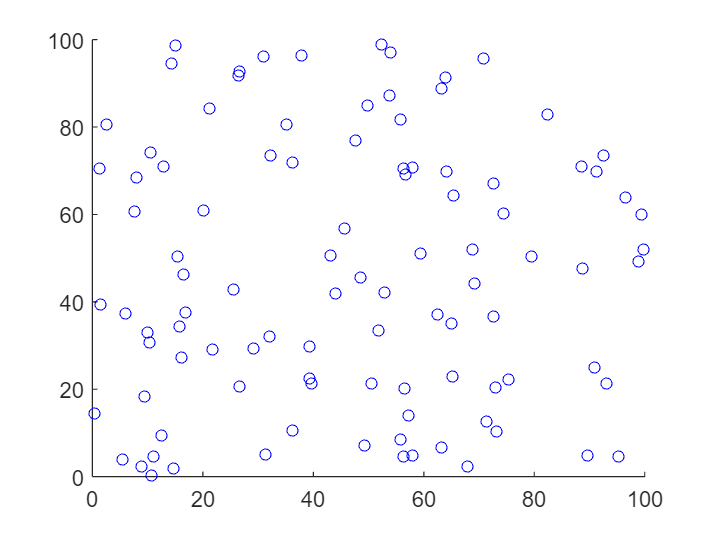

scatter(nodes(:,1),nodes(:,2),25,'ob')
xlim([0 100])
ylim([0 100])

A = generate_adj(nodes,r) % adjacency matrix

A =      0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0   

D = generate_degree(A) % degree matrix

D =     17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    18     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    24     0     0     0     0     0     0     0     0     0     0     0   

L = D-A % Laplacian matrix

L =     17     0     0     0     0     0     0     0     0    -1     0     0     0     0    -1    -1     0    -1     0     0     0     0     0     0     0     0     0     0    -1     0     0    -1     0     0     0     0     0    -1    -1    -1     0     0     0     0     0     0     0     0     0     0
     0    20     0    -1     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1    -1     0    -1     0     0     0     0     0     0     0     0     0     0    -1    -1     0     0
     0     0    18     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1    -1     0     0     0     0     0    -1     0     0     0    -1     0     0     0     0     0     0     0     0
     0    -1     0    24     0     0     0     0     0     0     0     0     0     0     0   

edges = generate_edges(A) % edges of the graph

edges =      1    10
     1    15
     1    16
     1    18
     1    29
     1    32
     1    38
     1    39
     1    40
     1    51


B = generate_inc(A,edges) % incidence matrix

B =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

disp("check if L = B*B': "+isequal(L,B*B'))

check if L = B*B': true


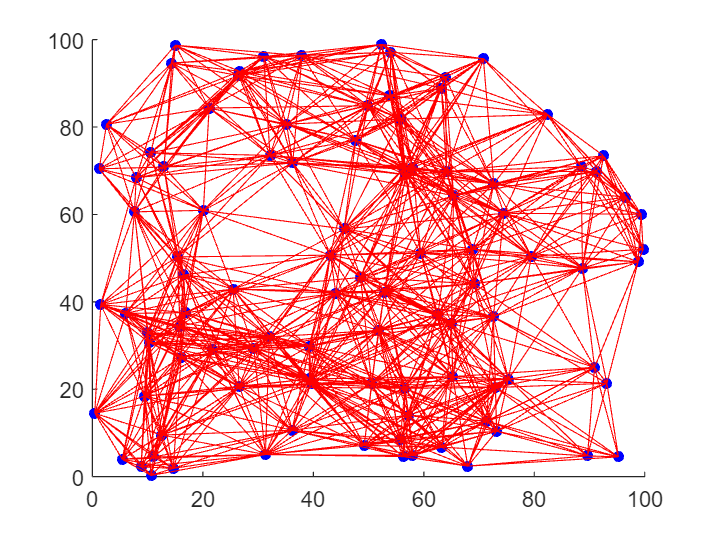

plot_nodes(nodes,edges)

x_values = 10*randn(N,1)+5;
% x_values = 10*rand(N,1)+5;
x_avg = mean(x_values)*ones(N,1)

x_avg =     6.4227
    6.4227
    6.4227
    6.4227
    6.4227
    6.4227
    6.4227
    6.4227
    6.4227
    6.4227


% Random gossip
x_rng_gossip = x_values;
t_rng_gossip = 0;
error_rng_gossip = zeros(max_iter*5,2);
for ii=1:max_iter*5
    idx1 = randi(N);
    list_adj = [find(A(idx1,:)~=0)];
    idx2 = list_adj(randi(length(list_adj)));
    e_i = zeros(N,1);
    e_j = zeros(N,1);
    e_i(idx1) = 1;
    e_j(idx2) = 1;
    W_ij = eye(N)-0.5*(e_i-e_j)*(e_i-e_j)';
    x_rng_gossip = W_ij*x_rng_gossip;
    t_rng_gossip = t_rng_gossip + 2;
    error_rng_gossip(ii,1) = t_rng_gossip;
    error_rng_gossip(ii,2) = norm(x_rng_gossip-x_avg,2);
end

% Geographic gossip
x_geo_gossip = x_values;
t_geo_gossip = 0;
error_geo_gossip = zeros(max_iter,2);
for ii=1:max_iter
    idx1 = randi(N);
    idx2 = randi(N);
    while idx1 == idx2
        idx2 = randi(N);
    end
    e_i = zeros(N,1);
    e_j = zeros(N,1);
    e_i(idx1) = 1;
    e_j(idx2) = 1;
    W_ij = eye(N)-0.5*(e_i-e_j)*(e_i-e_j)';
    x_geo_gossip = W_ij*x_geo_gossip;
    t_geo_gossip = t_geo_gossip + 2;
    error_geo_gossip(ii,1) = t_geo_gossip;
    error_geo_gossip(ii,2) = norm(x_geo_gossip-x_avg,2);
end

% Greedy Gossip
x_gg = x_values;
t_gg = 0;
error_gg = zeros(max_iter,2);
for ii=1:max_iter
    idx1 = randi(N);
    % idx2 = randi(length(list_adj));

    list_adj = [find(A(idx1,:)~=0)];
    distance_adj = abs(x_gg(list_adj)-x_gg(idx1));
    [max_err, idx2] = max(distance_adj);
    idx2 = list_adj(idx2);
    % if max_err >1e-7
    %     idx2 = list_adj(idx2);
    % else
    %     idx2 = randi(length(list_adj));
    % end

    e_i = zeros(N,1);
    e_j = zeros(N,1);
    e_i(idx1) = 1;
    e_j(idx2) = 1;
    W_ij = eye(N)-0.5*(e_i-e_j)*(e_i-e_j)';
    x_gg = W_ij * x_gg;
    t_gg = t_gg+2;
    error_gg(ii,1) = t_gg;
    error_gg(ii,2) = norm(x_gg-x_avg,2);
end

% Broadcast weighted gossip
s_wg = x_values;
w_wg = ones(N,1);
error_wg_gossip = zeros(max_iter*6,2);
t_wg_gossip = 0;
for ii=1:max_iter*6
    idx = randi(N);
    list_neighbor = [find(A(idx,:)~=0), idx];
    d = D(idx, idx);
    D_sum = eye(N);
    D_sum(idx, idx) = 1 / (d+1);
    D_sum(list_neighbor, idx) = 1 / (d+1);
    s_wg = D_sum*s_wg;
    w_wg = D_sum*w_wg;
    x_wg = s_wg./w_wg;

    t_wg_gossip = t_wg_gossip+1;

    error_wg_gossip(ii,1) = t_wg_gossip;
    error_wg_gossip(ii,2) = norm(x_wg-x_avg,2);
end

% Asynchronous ADMM
x_admm = x_values;
t_admm = 0;
z_admm = zeros(N,N);
nu_admm = zeros(N,N);
rho = 0.4;
error_admm = zeros(max_iter*5,2);
lists_adj = cell(N,1);
for ii=1:N
    lists_adj{ii} = find(A(ii,:)~=0);
end

for ii=1:max_iter*5
    idx1 = randi(N);
    idx2 = lists_adj{idx1}(randi(length(lists_adj{idx1})));
    x_admm(idx1) = (x_values(idx1)+sum(rho*z_admm(idx1,lists_adj{idx1})-nu_admm(idx1,lists_adj{idx1})))/(1+rho*D(idx1,idx1));
    x_admm(idx2) = (x_values(idx2)+sum(rho*z_admm(idx2,lists_adj{idx2})-nu_admm(idx2,lists_adj{idx2})))/(1+rho*D(idx2,idx2));

    z_admm(idx1,idx2) = 0.5*(x_admm(idx1)+x_admm(idx2));
    z_admm(idx2,idx1) = 0.5*(x_admm(idx1)+x_admm(idx2));
    nu_admm(idx1,idx2) = nu_admm(idx1,idx2) + rho*(x_admm(idx1)-z_admm(idx2,idx1));
    nu_admm(idx2,idx1) = nu_admm(idx2,idx1) + rho*(x_admm(idx2)-z_admm(idx1,idx2));

    t_admm = t_admm+4;
    error_admm(ii,1)=t_admm;
    error_admm(ii,2)=norm(x_admm-x_avg,2);
end

% Asynchronous Unicast PDMM

x_uni_pdmm = x_values;
t_uni_pdmm = 0;
xi_uni_pdmm = zeros(N,N);
c = 0.4;
error_uni_pdmm = zeros(max_iter*10,2);
lists_adj = cell(N,1);
for ii=1:N
    lists_adj{ii} = find(A(ii,:)~=0);
end

for ii=1:max_iter*10
    idx = randi(N);

    x_uni_pdmm(idx) = (x_values(idx)+sum(xi_uni_pdmm(idx,lists_adj{idx})))/(1+c*D(idx,idx));
    xi_uni_pdmm(lists_adj{idx},idx)=-xi_uni_pdmm(idx,lists_adj{idx})+2*c*x_uni_pdmm(idx);
    t_uni_pdmm = t_uni_pdmm+length(lists_adj{idx});

    error_uni_pdmm(ii,1)=t_uni_pdmm;
    error_uni_pdmm(ii,2)=norm(x_uni_pdmm-x_avg,2);
end

% async Broadcast PDMM

x_broad_pdmm = x_values;
t_broad_pdmm = 0;
xi_broad_pdmm = zeros(N,N);
c = 0.4;
error_broad_pdmm = zeros(max_iter,2);
lists_adj = cell(N,1);
for ii=1:N
    lists_adj{ii} = find(A(ii,:)~=0);
end

for ii=1:max_iter
    idx = randi(N);

    x_broad_pdmm(idx) = (x_values(idx)+sum(xi_broad_pdmm(idx,lists_adj{idx})))/(1+c*D(idx,idx));
    xi_broad_pdmm(lists_adj{idx},idx)=-xi_broad_pdmm(idx,lists_adj{idx})+2*c*x_broad_pdmm(idx);
    t_broad_pdmm = t_broad_pdmm+1;
    % t_broad_pdmm = t_broad_pdmm+length(lists_adj{idx});

    error_broad_pdmm(ii,1)=t_broad_pdmm;
    error_broad_pdmm(ii,2)=norm(x_broad_pdmm-x_avg,2);
end

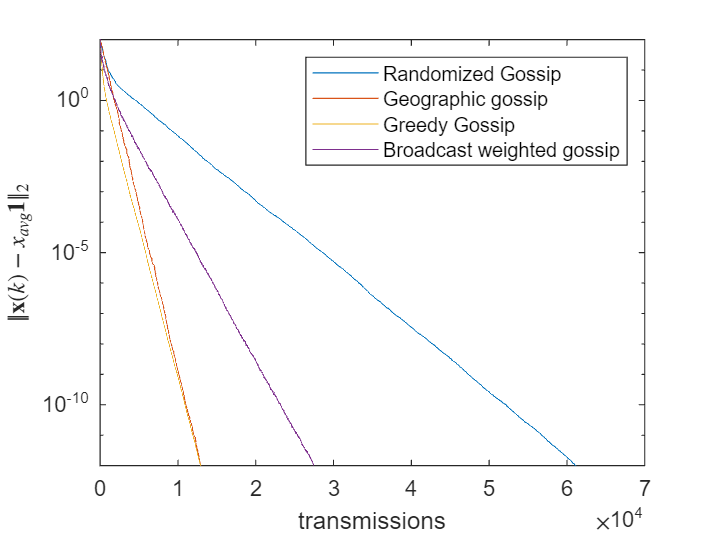

figure;
plot(error_rng_gossip(:,1),error_rng_gossip(:,2))
hold on
plot(error_geo_gossip(:,1),error_geo_gossip(:,2))
plot(error_gg(:,1),error_gg(:,2))
plot(error_wg_gossip(:,1),error_wg_gossip(:,2))

set(gca, 'YScale', 'log')
ylabel('$|\!|\mathbf{x}(k)-x_{avg}\mathbf{1}|\!|_2$', 'interpreter', 'latex')
xlabel("transmissions")
ylim([1e-12 1e2])
legend("Randomized Gossip","Geographic gossip","Greedy Gossip","Broadcast weighted gossip")
hold off

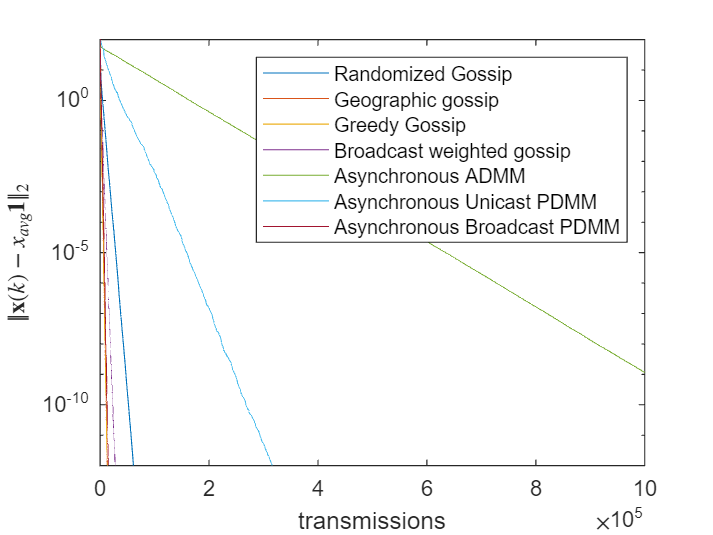

figure;
plot(error_rng_gossip(:,1),error_rng_gossip(:,2))
hold on
plot(error_geo_gossip(:,1),error_geo_gossip(:,2))
plot(error_gg(:,1),error_gg(:,2))
plot(error_wg_gossip(:,1),error_wg_gossip(:,2))
plot(error_admm(:,1),error_admm(:,2))
plot(error_uni_pdmm(:,1),error_uni_pdmm(:,2))
plot(error_broad_pdmm(:,1),error_broad_pdmm(:,2))

set(gca, 'YScale', 'log')
ylabel('$|\!|\mathbf{x}(k)-x_{avg}\mathbf{1}|\!|_2$', 'interpreter', 'latex')
xlabel("transmissions")
ylim([1e-12 1e2])
legend("Randomized Gossip","Geographic gossip","Greedy Gossip","Broadcast weighted gossip","Asynchronous ADMM","Asynchronous Unicast PDMM","Asynchronous Broadcast PDMM")
hold off

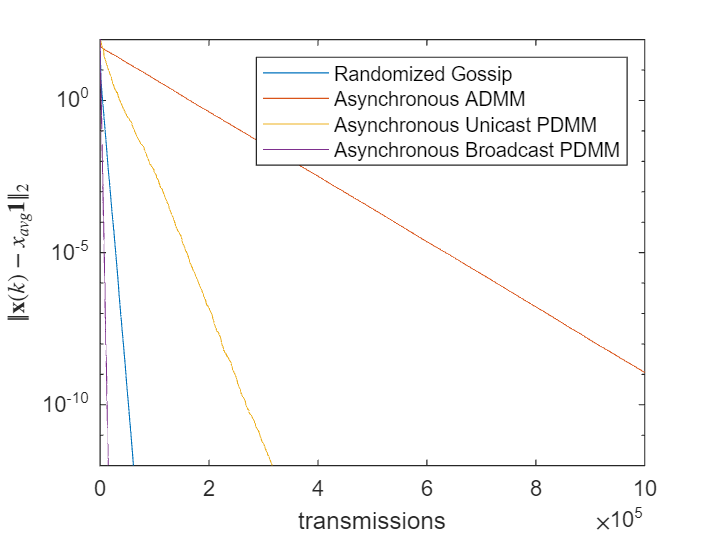

figure;
plot(error_rng_gossip(:,1),error_rng_gossip(:,2))
hold on
plot(error_admm(:,1),error_admm(:,2))
plot(error_uni_pdmm(:,1),error_uni_pdmm(:,2))
plot(error_broad_pdmm(:,1),error_broad_pdmm(:,2))

set(gca, 'YScale', 'log')
ylabel('$|\!|\mathbf{x}(k)-x_{avg}\mathbf{1}|\!|_2$', 'interpreter', 'latex')
xlabel("transmissions")
ylim([1e-12 1e2])
% xlim([0 5e5])
legend("Randomized Gossip","Asynchronous ADMM","Asynchronous Unicast PDMM","Asynchronous Broadcast PDMM")
hold off